## Parameters and Equilibrium Conditions

addpath(genpath(fileparts(which('pathfile.m'))))
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
% width = 1000; height = 1000;
% set(gcf,'position',[0,0,width,height])

P1 = [2 1 1 1 1 1];
P2 = [2 1 1 1 0.99 1];
P3 = [2 1 0.5 1 1 1];
P4 = [2 1 1 1 0.5 1];

E1 = [0 0 0];
E2 = [0 pi pi];

L3 = num2cell([P2,E1]);
L4 = num2cell([P2,E2]);
L7 = num2cell([P4,E1]);
L8 = num2cell([P4,E2]);
ue = 0;
C = [1 0 0 0 0 0]; 
D = 0;

## Case 3: P2, E1

% pull parameters and initial conditions for case
[m0, m1, m2, l1, l2, g, ye, theta1e, theta2e] = deal(L3{:});
xe = [ye,theta1e,theta2e,0,0,0]';
mt = m0 + m1 + m2;
M = [mt, -m1*l1*cos(theta1e), -m2*l2*cos(theta2e);
    -m1*l1*cos(theta1e), m1*l1^2, 0;
    -m2*l2*cos(theta2e), 0, m2*l2^2];
G = [0,0,0;0,m1*l1*g*cos(theta1e),0;0,0,m2*l2*g*cos(theta2e)];
W = [1 0 0]';
A = [zeros(3), eye(3); M^-1*(-G), zeros(3)]

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -0.5000   -0.5000         0         0         0
         0   -1.5000   -0.5000         0         0         0
         0   -0.5051   -1.5152         0         0         0


B = [0;0;0;M^-1*W]

B =          0
         0
         0
    0.5000
    0.5000
    0.5051



p = -linspace(.7,2.5,6)

p =    -0.7000   -1.0600   -1.4200   -1.7800   -2.1400   -2.5000


K = -place(A,B,p)

K = 	1.0e+03 *

   -0.0199   -6.9009    6.7837   -0.0895   -3.9317    3.9620



del_deg = 0.3049

del_deg = 0.3049

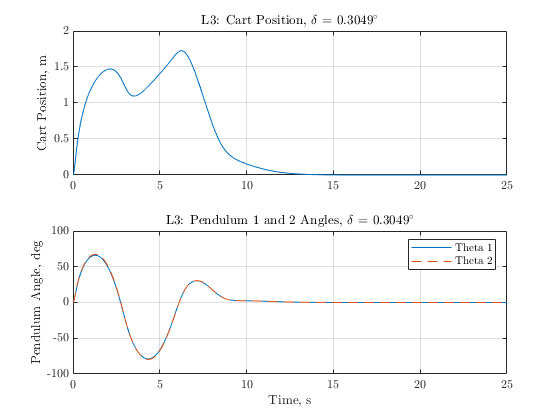

del = deg2rad(del_deg);

IC  = [0,theta1e-del,theta2e+del,0,0,0]';
tspan = [0 25];
[t,x] = ode45(@(t,x) xfun_NLSF(x,m0,m1,m2,l1,l2,g,mt,t,K,xe,ue),tspan,IC); % linear

figure
subplot(2,1,1)
plot(t,x(:,1))
ylabel('Cart Position, m')
title("L3: Cart Position, $\delta$ = " + num2str(rad2deg(del)) + "$^{\circ}$")
grid on
subplot(2,1,2)
plot(t,x(:,2)*180/pi)
grid on
hold on
plot(t,x(:,3)*180/pi,'--')
title("L3: Pendulum 1 and 2 Angles, $\delta$ = " + num2str(rad2deg(del)) + "$^{\circ}$")
ylabel('Pendulum Angle, deg')
xlabel('Time, s')
legend('Theta 1','Theta 2')

## Case 4: P2, E2

% pull parameters and initial conditions for case
[m0, m1, m2, l1, l2, g, ye, theta1e, theta2e] = deal(L4{:});
xe = [ye,theta1e,theta2e,0,0,0]';
mt = m0 + m1 + m2;
M = [mt, -m1*l1*cos(theta1e), -m2*l2*cos(theta2e);
    -m1*l1*cos(theta1e), m1*l1^2, 0;
    -m2*l2*cos(theta2e), 0, m2*l2^2];
G = [0,0,0;0,m1*l1*g*cos(theta1e),0;0,0,m2*l2*g*cos(theta2e)];
W = [1 0 0]';
A = [zeros(3), eye(3); M^-1*(-G), zeros(3)];
B = [0;0;0;M^-1*W];

p = -linspace(.7,2.5,6)

p =    -0.7000   -1.0600   -1.4200   -1.7800   -2.1400   -2.5000


K = -place(A,B,p)

K = 	1.0e+04 *

   -0.0020   -2.5632    2.5435   -0.0090   -2.5635    2.5309



del_deg = 0.0287

del_deg = 0.0287

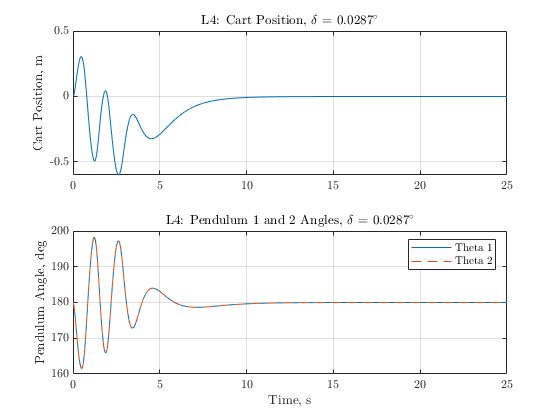

del = deg2rad(del_deg);

IC  = [0,theta1e-del,theta2e+del,0,0,0]';
tspan = [0 25];
[t,x] = ode45(@(t,x) xfun_NLSF(x,m0,m1,m2,l1,l2,g,mt,t,K,xe,ue),tspan,IC); % linear

figure
subplot(2,1,1)
plot(t,x(:,1))
ylabel('Cart Position, m')
title("L4: Cart Position, $\delta$ = " + num2str(rad2deg(del)) + "$^{\circ}$")
grid on
subplot(2,1,2)
plot(t,x(:,2)*180/pi)
grid on
hold on
plot(t,x(:,3)*180/pi,'--')
title("L4: Pendulum 1 and 2 Angles, $\delta$ = " + num2str(rad2deg(del)) + "$^{\circ}$")
ylabel('Pendulum Angle, deg')
xlabel('Time, s')
legend('Theta 1','Theta 2')

## Case 7: P4, E1

% pull parameters and initial conditions for case
[m0, m1, m2, l1, l2, g, ye, theta1e, theta2e] = deal(L7{:});
xe = [ye,theta1e,theta2e,0,0,0]';
mt = m0 + m1 + m2;
M = [mt, -m1*l1*cos(theta1e), -m2*l2*cos(theta2e);
    -m1*l1*cos(theta1e), m1*l1^2, 0;
    -m2*l2*cos(theta2e), 0, m2*l2^2];
G = [0,0,0;0,m1*l1*g*cos(theta1e),0;0,0,m2*l2*g*cos(theta2e)];
W = [1 0 0]';
A = [zeros(3), eye(3); M^-1*(-G), zeros(3)];
B = [0;0;0;M^-1*W];

p = -linspace(.7,2.5,6)

p =    -0.7000   -1.0600   -1.4200   -1.7800   -2.1400   -2.5000


K = -place(A,B,p)

K =   -10.0338  -68.7157    6.6087  -45.2051  -39.7145   32.8598



del_deg = 55.8027

del_deg = 55.8027

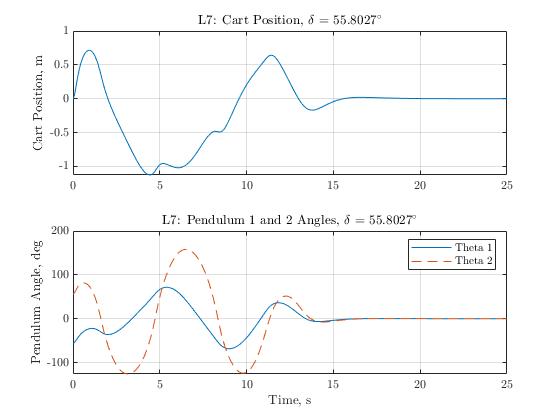

del = deg2rad(del_deg);

IC  = [0,theta1e-del,theta2e+del,0,0,0]';
tspan = [0 25];
[t,x] = ode45(@(t,x) xfun_NLSF(x,m0,m1,m2,l1,l2,g,mt,t,K,xe,ue),tspan,IC); % linear

figure
subplot(2,1,1)
plot(t,x(:,1))
ylabel('Cart Position, m')
title("L7: Cart Position, $\delta$ = " + num2str(rad2deg(del)) + "$^{\circ}$")
grid on
subplot(2,1,2)
plot(t,x(:,2)*180/pi)
grid on
hold on
plot(t,x(:,3)*180/pi,'--')
title("L7: Pendulum 1 and 2 Angles, $\delta$ = " + num2str(rad2deg(del)) + "$^{\circ}$")
ylabel('Pendulum Angle, deg')
xlabel('Time, s')
legend('Theta 1','Theta 2')

## Case 8: P4, E2

% pull parameters and initial conditions for case
[m0, m1, m2, l1, l2, g, ye, theta1e, theta2e] = deal(L8{:});
xe = [ye,theta1e,theta2e,0,0,0]';
mt = m0 + m1 + m2;
M = [mt, -m1*l1*cos(theta1e), -m2*l2*cos(theta2e);
    -m1*l1*cos(theta1e), m1*l1^2, 0;
    -m2*l2*cos(theta2e), 0, m2*l2^2];
G = [0,0,0;0,m1*l1*g*cos(theta1e),0;0,0,m2*l2*g*cos(theta2e)];
W = [1 0 0]';
A = [zeros(3), eye(3); M^-1*(-G), zeros(3)];
B = [0;0;0;M^-1*W];

p = -linspace(.7,2.5,6)

p =    -0.7000   -1.0600   -1.4200   -1.7800   -2.1400   -2.5000


K = -place(A,B,p)

K =   -10.0338 -257.9149  165.7066  -45.2051 -258.9351  116.4650



del_deg = 2.6486

del_deg = 2.6486

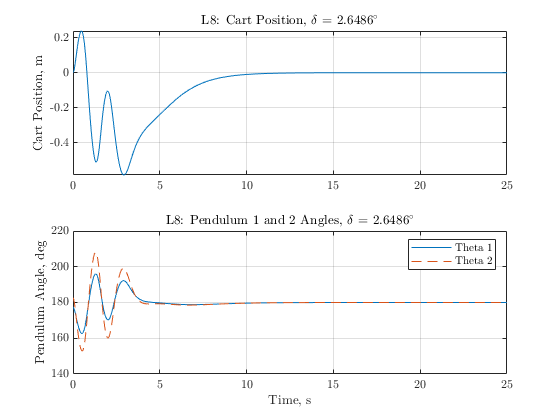

del = deg2rad(del_deg);

IC  = [0,theta1e-del,theta2e+del,0,0,0]';
tspan = [0 25];
[t,x] = ode45(@(t,x) xfun_NLSF(x,m0,m1,m2,l1,l2,g,mt,t,K,xe,ue),tspan,IC); % linear

figure
subplot(2,1,1)
plot(t,x(:,1))
ylabel('Cart Position, m')
title("L8: Cart Position, $\delta$ = " + num2str(rad2deg(del)) + "$^{\circ}$")
grid on
subplot(2,1,2)
plot(t,x(:,2)*180/pi)
grid on
hold on
plot(t,x(:,3)*180/pi,'--')
title("L8: Pendulum 1 and 2 Angles, $\delta$ = " + num2str(rad2deg(del)) + "$^{\circ}$")
ylabel('Pendulum Angle, deg')
xlabel('Time, s')
legend('Theta 1','Theta 2')

## Nonlinear

function dxdt = xfun_NLSF(x, m0, m1, m2, l1, l2, g, mt,t,K,xe,ue)
u = ue + K*(x-xe);
% u = 0;
M = [mt, -m1*l1*cos(x(2)), -m2*l2*cos(x(3));
    -m1*l1*cos(x(2)), m1*l1^2, 0;
    -m2*l2*cos(x(3)), 0, m2*l2^2];
G = [m1*l1*sin(x(2))*x(5)^2 + m2*l2*sin(x(3))*x(6)^2;
    m1*l1*g*sin(x(2));
    m2*l2*g*sin(x(3))];
W = [1;0;0];
q = x(1:3);
qdot = x(4:6);
qddot = M^-1*(W*u-G);
dxdt = [qdot; qddot];
end